img = imread("boston night.jpg")

img = 3456×5184×3 uint8 array
img(:,:,1) =

     1     0     2     5     3     1     0     1     3     3     3     2     0     0     0     1     1     1     2     3     3     3     3     2     2     2     3     3     1     2     3     3     3     2     1     0     1     0     0     1     1     3     3     3     3     2     1     1     1     0     0     2     3     3     1     0     1     1     1     1     0     1     1     1     1     0     0     1     2     3     3     3     4     2     1     2     2     3     3     2     0     1     1     0     1     0     0     0     2     2     3     4     3     1     0     1     4     4     5     4     2     3     3     1     0     0     0     1     2     3     2     1     2     2     0     0     0     0     0     0     1     0     1     0     0     1     0     0     3     0     0     1     0     0     0     1     1     2     2     3     2     0     0     1     5     3     1     1     1     1     1     1     2     0     0     3     5     3     1  

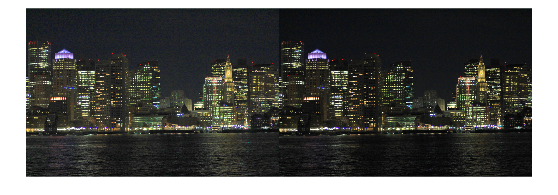

gamma = 0.5;
gamma2 = 1.3;
%imgGamma = im2double(img) .^ gamma;
%imgGamma = im2uint8(imgGamma);

imgGammaHsv = rgb2hsv(img);
imgGammaHsv(:, :, 3) = im2double(imgGammaHsv(:, :, 3)) .^ gamma;
imgGamma = hsv2rgb(imgGammaHsv);
imgGamma = im2uint8(imgGamma);

imgGamma2Hsv = rgb2hsv(img);
imgGamma2Hsv(:, :, 3) = im2double(imgGammaHsv(:, :, 3)) .^ gamma2;
imgGamma2 = hsv2rgb(imgGamma2Hsv);
imgGamma2 = im2uint8(imgGamma2);
montage({imgGamma, imgGamma2});

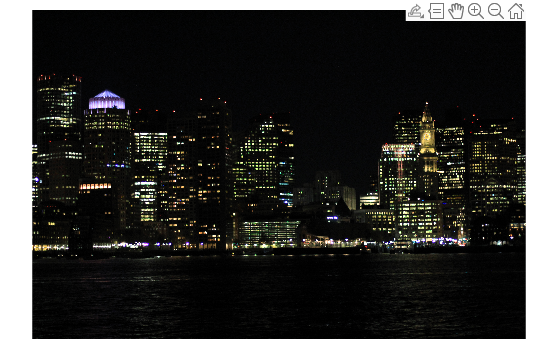

imgAdjustHsv = rgb2hsv(img);
imgAdjustHsv(:, :, 3) = imadjust(imgAdjustHsv(:, :, 3));
imgAdjust = hsv2rgb(imgAdjustHsv);
imgAdjust = im2uint8(imgAdjust);


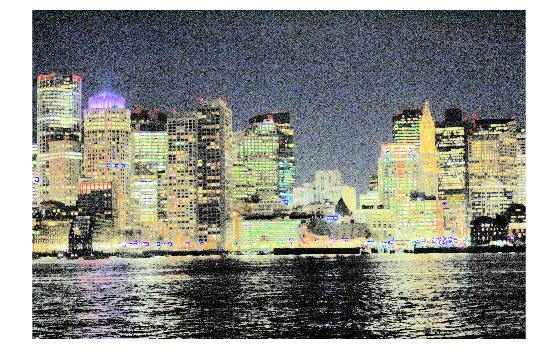

imgEqHsv = rgb2hsv(img);
imgEqHsv(:, :, 3) = histeq(imgEqHsv(:, :, 3));
imgEq = hsv2rgb(imgEqHsv);
imgEq = im2uint8(imgEq);


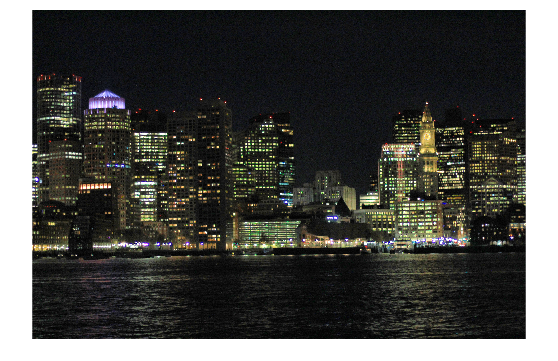

imgAdaptHsv = rgb2hsv(img);
imgAdaptHsv(:, :, 3) = adapthisteq(imgAdaptHsv(:, :, 3));
imgAdapt = hsv2rgb(imgAdaptHsv);
imgAdapt = im2uint8(imgAdapt);
